# Gauntlet Report

**Rucha Dave, Devlin Ih**

Goal: Use a combination of potential fields and gradient descent to navigate a robot through a cluttered environment to the Barrel of Benevolence.

## Introduction

For this project, we chose Level 1, where the coordinates of the BoB, obstacles, and walls are given. From these, a potential field is to be created and gradient descent is to be executed. 

- To attack this problem, we first created a potential field with the walls and obstacles as sources and the barrel as a sink. In order to ensure that they were detected accurately, the different sources and sinks were weighted differently. 

- Then, we created a surface map to ensure that the path towards the sink was unobstructed and that there were no unexpected valleys or hills in the way. This also involved creating a quiver plot for the field to visually understand the path.

- Finally, we ran the simulation and collected encoder data for the actual path taken by the Neato to compare it to the predicted path.

## Path Planning

**Lidar Map:**

Before calculating the next rotation and size during gradient descent, a LIDAR scan was conducted from the current position and heading of the robot. Every one of these scans is in a different frame. We can translate all of these scans to the global frame and plot them with the following code:

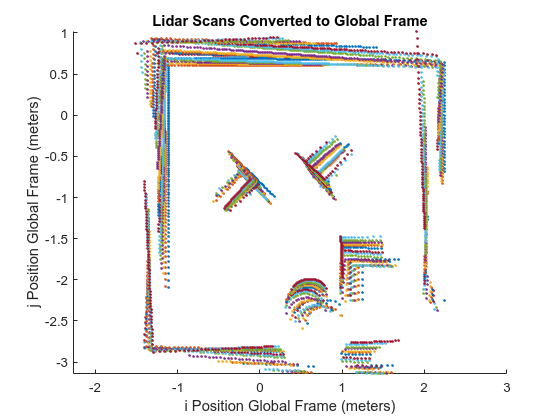

clf;
hold on;
axis equal;

% Load the scan data
load scandata.mat
position = scan_data(1:2,:);
heading = scan_data(3:4,:);
radius = scan_data(5:end,:);
theta = deg2rad([0:359]');
[x,y] = pol2cart(theta, radius);

for i = 1:size(position, 2)
    current_heading = heading(:,i)/norm(heading(:,i));
    [phi, ~] = cart2pol(current_heading(1), current_heading(2));
    current_i = x(:,i)';
    current_j = y(:,i)';
    scanned_points_neato = [current_i; current_j; ones(1,360)];

    T = [1 0 position(1, i);...
         0 1 position(2, i);...
         0 0 1];
    R = [cos(phi) -sin(phi) 0;...
         sin(phi) cos(phi)  0;...
         0        0         1];
    
    scanned_points_global = T * R * scanned_points_neato;
    plot(scanned_points_global(1,:), scanned_points_global(2,:), '.')
end

xlabel("i Position Global Frame (meters)")
ylabel("j Position Global Frame (meters)")
title("Lidar Scans Converted to Global Frame")

As you can see, the elements of the gauntlet are clearly visible, but it is not *quite* right. This is due to the error of where the robot actually is vs where the robot ***thinks*** it is increasing after every step. We recorded where the robot thoguht it was at the time of taking a scan. Thus, the points don't entirely line up.

**Potential Field:**

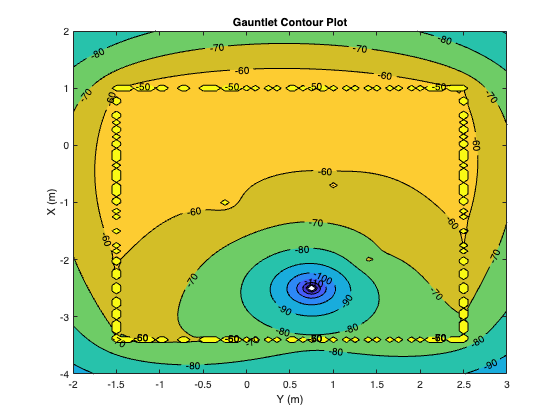

clf;

% Create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% Define barrel and obstacles
v = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

% Define sources at lines for walls
for a = -1.5:0.01:2.5
    v = v - 0.05*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - 0.05*log(sqrt((x-a).^2 + (y+3.4).^2));
end

for b = -3.37:0.01:1
    v = v - 0.05*log(sqrt((x+1.5).^2 + (y-b).^2));
    v = v - 0.05*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% Draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
title('Gauntlet Contour Plot');
xlabel('Y (m)');
ylabel('X (m)');


$$\textrm{Equation}:\;V\left(x,y\right)=20*\ln \sqrt{{\left(x-0\ldotp 75\right)}^2 +{\left(y+2\ldotp 5\right)}^2 }-2*\ln \sqrt{{\left(x+0\ldotp 25\right)}^2 +{\left(y+1\right)}^2 }-2\ldotp 5*\ln \sqrt{{\left(x-1\ldotp 41\right)}^2 +{\left(y+2\right)}^2 }-0\ldotp 4*\ln \sqrt{{\left(x-1\right)}^2 +{\left(y+0\ldotp 7\right)}^2 }$$


**Quiver Plot: **

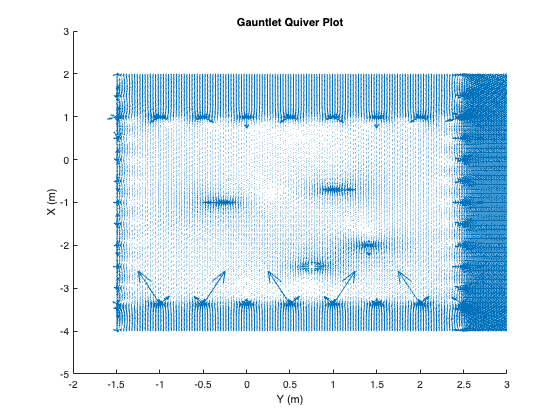

clf;
hold on;

% Create a meshgrid
[x,y]=meshgrid(-1.5:0.03:3,-4:0.03:2);

% Add sources (obstacles and BoB)
fx = ((x-0.75)./((x-0.75).^2+(y+2.5).^2)) - ((x+0.25)./((x+0.25).^2+(y+1).^2)) - ((x-1.41)./((x-1.41).^2+(y+2).^2)) - ((x-1)./((x-1).^2+(y+0.7).^2));
fy = ((y+2.5)./((x-0.75).^2+(y+2.5).^2)) - ((y+1)./((x+0.25).^2+(y+1).^2)) - ((y+2)./((x-1.41).^2+(y+2).^2)) - ((y+0.7)./((x-1).^2+(y+0.7).^2));

% Add walls
for a = -1.5:0.5:2.5
    fx = fx - ((x-a)./((x-a).^2 + (y-1).^2));
    fy = fy - ((y-1)./((x-a).^2 + (y-1).^2));

    fx = fx - ((x-a)./((x-a).^2 + (y+3.4).^2));
    fy = fy - ((y+3.37)./((x-a).^2 + (y+3.4).^2));
end

for b = -4:0.5:2
    fx = fx - ((x+1.5)./((x+1.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x+1.5).^2 + (y-b).^2));
 
    fx = fx - ((x-2.5)./((x-2.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x-2.5).^2 + (y-b).^2));
end

% Plot
title("Gauntlet Quiver Plot");
xlabel("Y (m)");
ylabel("X (m)");
quiver(x,y,fx,fy,20)

**Gradient Descent Path (Expected):**

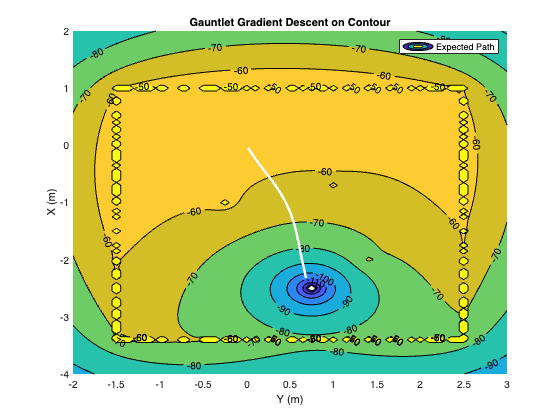

clf;
hold on;

% Get expected positions of Neato
final_positions = [];

wheelBase = 0.235;          
lambda = 0.01;

% Equation for contour
syms x y;
f = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

% Find gradient of contour
grad = gradient(f, [x, y]);

% Initialize position
position = [0; 0];

% Gather 23 points
counter = 23;
while counter > 0
    % Get gradient for point
    gradValue = -1*double(subs(grad, {x, y}, {position(1), position(2)}));

    % Update the position for the next iteration
    position = position + (gradValue*lambda);
    final_positions = [final_positions position];
    counter = counter - 1;
end
 
% Create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% Draw contours
title("Gauntlet Gradient Descent on Contour")
xlabel("Y (m)")
ylabel("X (m)")
contourf(x, y, v, 'k', 'ShowText', 'On');

% Plot neato path expected
plot(final_positions(1, :), final_positions(2, :), 'w', 'LineWidth', 2.5)
legend("Expected Path")

## Navigate Gauntlet

**Gradient Descent Path (Actual):**

clf;
hold on;

d = 0.235;

% Get encoder data
encoder_data = table2array(readtable("encoders.csv"));

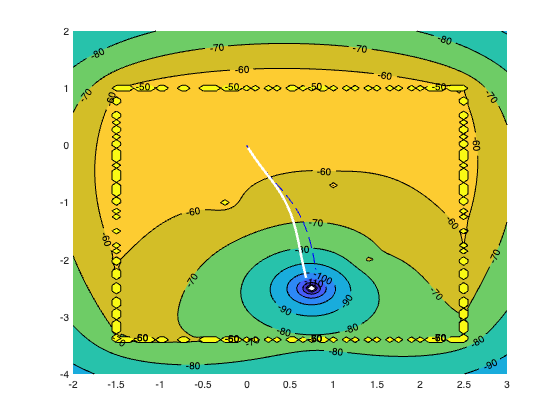

% Get time into array and initalize to beginning
timeSeconds = encoder_data(:, 1);
timeSeconds = timeSeconds - timeSeconds(1);

% Get left and right wheel distances
encoderLeftDis = encoder_data(:, 2);
encoderRightDis = encoder_data(:, 3);

% Find velocity of each wheel at each point
velLeft = diff(encoderLeftDis) ./ diff(timeSeconds);
velRight = diff(encoderRightDis) ./ diff(timeSeconds);

% Find angular and linear speed of neato
angularReal = (velRight - velLeft) ./ (d);
linSpeedReal = (velRight + velLeft) ./ 2;

% Find angle at each point as well as linear speed in x and y
thetaReal = cumtrapz(timeSeconds(1:end-1), angularReal(1:end));
speedX = linSpeedReal(:) .* cos(thetaReal);
speedY = linSpeedReal(:).* sin(thetaReal);

% Use speed to find position of x and y at each point
posX = cumtrapz(timeSeconds(1:end-1), speedX(1:end));
posY = cumtrapz(timeSeconds(1:end-1), speedY);
pos = [posX, posY];

% Create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% Draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
plot(posX(:, 1), posY(:, 1), "b--"); % actual
plot(final_positions(1, :), final_positions(2, :), 'w', 'LineWidth', 2.5) % expected

Time taken: 19.1 seconds

Distance: 